# Transformación Invariante de Krajník

## ¿Qué es?

La transformación invariante de Krajník es un método para obtener imágenes invariantes a cambios de iluminación. Se basa en el uso de imágenes intrínsecas, que separan las propiedades intrínsecas de la superficie (reflectancia) de las propiedades extrínsecas (iluminación). Este enfoque permite reducir la influencia de sombras y variaciones de iluminación en la imagen.

## Funcionamiento básico de la transformación

**1. Modelo Espectral RGB:**

La respuesta espectral de un canal específico $\rho_k$ (con 𝑘 = {𝑟,𝑔,𝑏} ) se define como: 


$$\rho_k = \sigma \int E(\lambda) S(\lambda) Q_k(\lambda) d\lambda$$


donde:

- $\sigma$: factor constante que denota el sombreado de Lambert.

- $E(\lambda)$: iluminación incidente en el elemento de superficie percibida.

- $S(\lambda)$: reflectancia espectral de la superficie.

- $Q(\lambda)$: sensibilidad espectral del canal $k$.

- $\lambda$: longitud de onda.

**2. Transformación Logarítmica:**

Se transforma el modelo a un espacio logarítmico para hacer que sea invariante a la iluminación. Esto se realiza calculando el logaritmo de la respuesta espectral relativa a un canal de referencia (e.g., azul):


$$\chi_{k,g} = \log \frac{\rho_{r,g}}{\rho_{b}}
$$


**3. Proyección a un Espacio Invariante:**

Se proyecta el espacio logarítmico-cromático en una dirección $\theta$ para obtener la imagen invariante.


$$I_{\theta} = \chi_{r} \cos \theta + \chi_{g} \sin \theta
$$


**4. Minimización de la Entropía:**

Se determina el ángulo $\theta$ que minimiza la entropía de la imagen proyectada, para que sea lo más invariante posible a la iluminación.


$$E_{\theta} = -\sum_{i} H_{\theta}(i) \log H_{\theta}(i)$$


donde:

- $H_{\theta}(i)$: histograma proyectado en una dirección $\theta$.

## Análisis de la Implementación

**1. Parámetros de Entrada:**

- $RGB$: imagen en formato RGB.

- $\theta$: ángulo de proyección.

**2. Separación de los Canales:**

Primero, la función guarda por separado cada canal de la imagen $R$, $G$, y $B$.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

**3. A continuacion calcula **$x_r$** y **$x_g$**.**

logR = log(R + 1); % Agrego 1 para evitar log(0)
logG = log(G + 1);
logB = log(B + 1);

psi1 = logR - logG;
psi2 = logG - logB;

**4. Calculo del parámetro **$\theta$

El parámetro $\theta$ se cancula en una función a parte y se pasa como parámetro.

angles = linspace(0, pi, 180);
min_entropy = Inf;
theta = 0;

for angle = angles
    I_proj = x_r * cos(angle) + x_g * sin(angle);
    counts = histcounts(I_proj(:), 256, 'Normalization', 'probability');
    entropy_val = -sum(counts .* log(counts + eps));

    if entropy_val < min_entropy
        min_entropy = entropy_val;
        theta = angle;
    end
end

**5. Transformación Invariante:**

Finalmente, la función realiza la transformación invariante con el ángulo $\theta$:

I_Krajnik = x_r * cos(theta) + x_g * sin(theta);

## Código completo

function theta = calcular_theta_krajnik(imagen)
    % Separar los canales RGB y calcular la cromaticidad logarítmica
    logR = log(double(imagen(:,:,1)) + 1);
    logG = log(double(imagen(:,:,2)) + 1);
    logB = log(double(imagen(:,:,3)) + 1);

    % Componentes cromáticas
    x_r = logR - logG;
    x_g = logG - logB;

    % Definir el rango de ángulos y valor inicial de entropía mínima
    angles = linspace(0, pi, 180);
    min_entropy = Inf;
    theta = 0;

    % Encontrar el ángulo que minimiza la entropía
    for angle = angles
        I_proj = x_r * cos(angle) + x_g * sin(angle);
        counts = histcounts(I_proj(:), 256, 'Normalization', 'probability');
        entropy_val = -sum(counts .* log(counts + eps));

        if entropy_val < min_entropy
            min_entropy = entropy_val;
            theta = angle;
        end
    end
end

function I_Krajnik = krajnik_transform(RGB, theta)
    % Separación de la imagen RGB por canales en double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Cálculo la cromaticidad logarítmica mas 1 para evitar log(0)
    logR = log(R + 1);
    logG = log(G + 1);
    logB = log(B + 1);
    
    % Cálculo de x_r y x_g
    x_r = logR - logG;
    x_g = logG - logB;
    
    % Transformación invariante
    I_Krajnik = x_r * cos(theta) + x_g * sin(theta);
end

Un ejemplo de una imagen del programa y su correspondiente transformación:

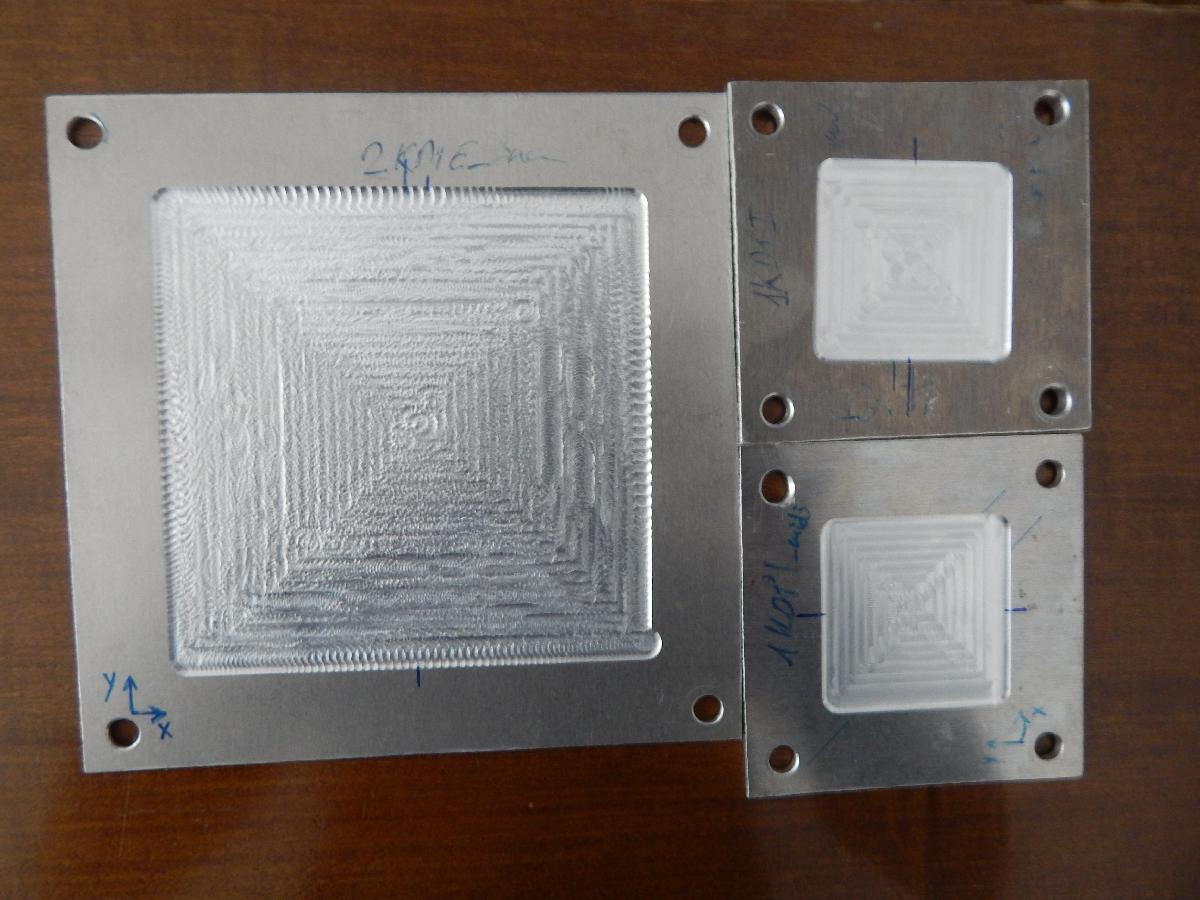    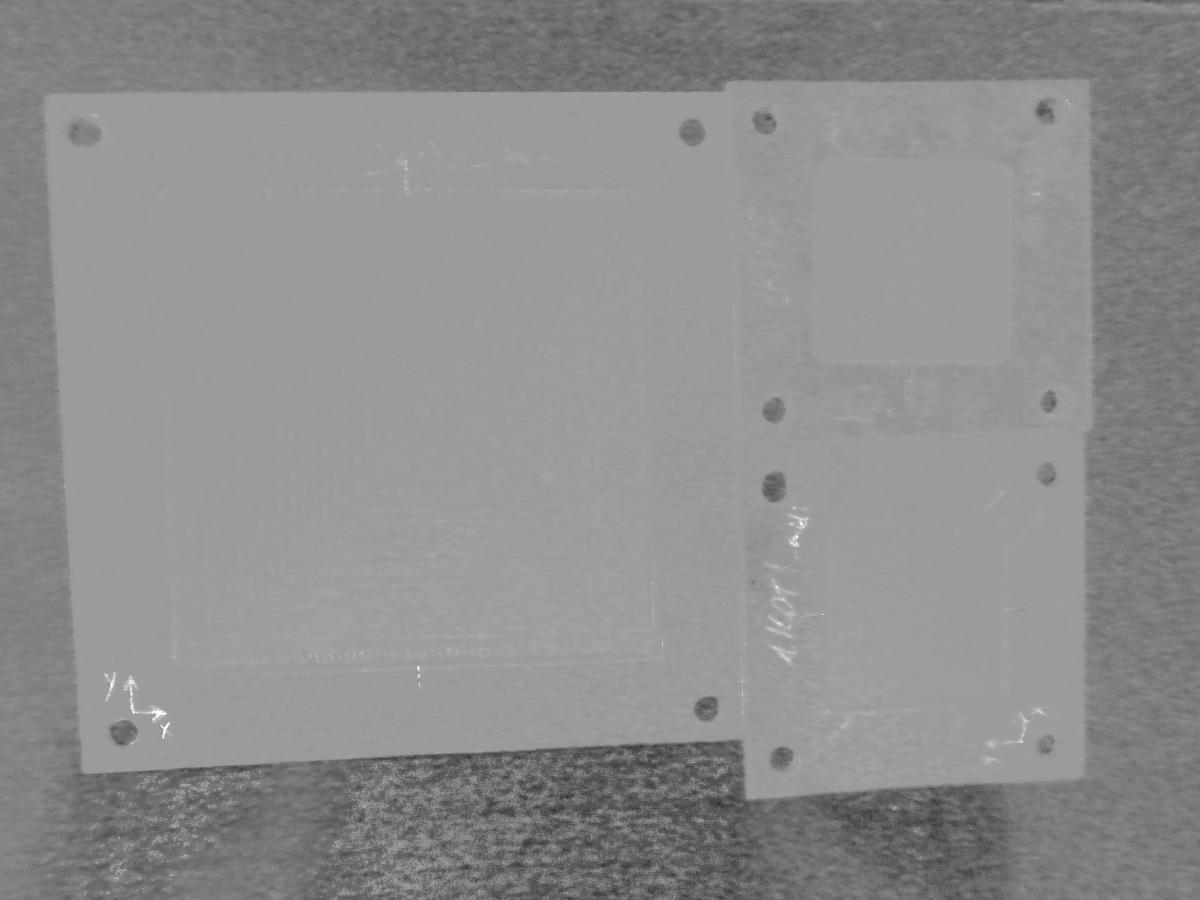

## Referencias

- Krajník, T., Blažiček, J., & Santos, J. M. "Visual Road Following Using Intrinsic Images," *IEEE Intelligent Transportation Systems (ITSC)*, pp. 1640-1646, 2015.